# CÓDIGO DESENVOLVIDO BASEADO NO MÉTODO DOS ELEMENTOS FINITOS UTILIZANDO A FORMULAÇÃO GUF 

# CLEANING

clc; clear; close all

## APPROXIMATION

APP = [2 2 2]; 

## MESH

mesh.ney = 14; % number of elements in Y
mesh.nex = 14; % number of elements in X
mesh.Lx = 1;   % length in X 
mesh.Ly = 1;   % length in Y
fprintf('a = %d',mesh.Lx)

a = 1

fprintf('b = %d',mesh.Ly)

b = 1

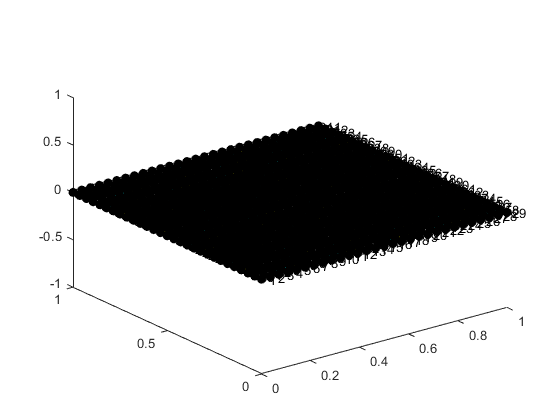

mesh.type = 'Q9';
[ mesh ] = create_mesh( mesh );

## THEORY

theory = 'EQ'; % EQ - Equivalent Single Layer
               % LW - Layerwise
               if strcmp(theory,'EQ')
                   fprintf('Equivalent Single Layer')
               elseif strcmp(theory,'LW')
                   fprintf('Layerwise')
               end

Equivalent Single Layer

## MATERIAL 1

mat(1).E1 = 25; % YOUNG MODULUS
mat(1).E2 =  1; 
mat(1).E3 =  10; 
mat(1).G12 =  0.5; % SHEAR MODULUS
mat(1).G13 =  0.5; 
mat(1).G23 =  0.2; 
mat(1).nu12 = 0.25;  % POISSON RATIO
mat(1).nu13 = 0.25;  
mat(1).nu23 = 0.25;  

## MATERIAL 2

mat(2).E1 = 25; % YOUNG MODULUS
mat(2).E2 =  1; 
mat(2).E3 =  10; 
mat(2).G12 =  0.5; % SHEAR MODULUS
mat(2).G13 =  0.5; 
mat(2).G23 =  0.2; 
mat(2).nu12 = 0.25;  % POISSON RATIO
mat(2).nu13 = 0.25;  
mat(2).nu23 = 0.25;  

## MATERIAL 3

mat(3).E1 = 25; % YOUNG MODULUS
mat(3).E2 =  1; 
mat(3).E3 =  10; 
mat(3).G12 =  0.5; % SHEAR MODULUS
mat(3).G13 =  0.5; 
mat(3).G23 =  0.2; 
mat(3).nu12 = 0.25;  % POISSON RATIO
mat(3).nu13 = 0.25;  
mat(3).nu23 = 0.25;  

## GEOMETRY 1

geo(1).h = 0.01;         % THICKNESS
geo(1).z_top = 0.015;
geo(1).z_low = 0.005;
geo(1).theta = 0;     % ANGLE

## GEOMETRY 2

geo(2).h = 0.01;         % THICKNESS
geo(2).z_top = 0.005;
geo(2).z_low =-0.005;
geo(2).theta = pi/2;     % ANGLE

## GEOMETRY 3

geo(3).h = 0.01;         % THICKNESS
geo(3).z_top =-0.005;
geo(3).z_low =-0.015;
geo(3).theta = 0;     % ANGLE

NL = length(geo);     % NUMBER OF LAYERS

## DEGREES OF FREEDOM

[ dof ] = degrees_of_freedom( APP, mesh, NL, theory );


Layer has 3 degrees of freedom in X direction 
Layer has 3 degrees of freedom in Y direction 
Layer has 3 degrees of freedom in Z direction 

Laminate has 3 degrees of freedom in X direction 
Laminate has 3 degrees of freedom in Y direction 
Laminate has 3 degrees of freedom in Z direction 


## BOUNDARY CONDITIONS

typeofBC = 'ssss'; % 'ssss' = Simply supported
                   % 'cccc' = Clamped
if strcmp(typeofBC,'ssss')
    fprintf('Simply supported plate')
elseif strcmp(typeofBC,'cccc')
    fprintf('Clamped plate')
end

Simply supported plate

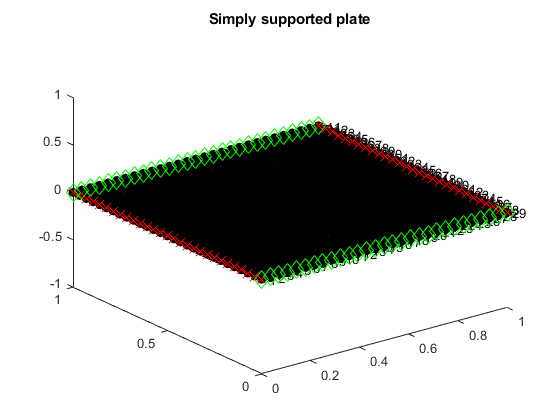


[ fixedNode ] = Boundary_Condition( mesh, typeofBC );

[ dof ] = free_DOF( dof, fixedNode, mesh  );

## APPLIED PRESSURE

type_Load = 'uniform'; % UNIFORM LOAD = uniform
                       % SINUSOIDAL LOAD = sinusoidal
%    X Y Z
P = [0 0 1;  % TOP
     0 0 0]; % BOTTOM

## COMPUTING GLOBAL STIFFNESS

[ S ] = shape_function( mesh );
[ KEN ] = local_stiffness_allocation( dof, mesh  );
for ply = 1 : NL
    % COMPUTING PLY STIFFNESS
    [ stiffness ] = Hook_law( mat, geo, ply );
    
    %COMPUTING KERNELS
    [ Z ] = z_matrix( APP, geo, ply, stiffness, theory );
    [ KE ] = local_stiffness( dof, mesh, S, Z );
    [ KEN ] = assembly_ESL( KE, KEN);
end
[ KG ] = global_stiffness_matrix( dof, KEN, mesh );

## COMPUTING LOAD VECTOR

[ D ] = D_ESL( dof, NL, geo );
switch type_Load
    case 'sinusoidal'
        [ Fg ] = sinusoidal_load( dof, mesh, D, P );
    case 'uniform' 
        [ Fg ] = uniform_load( dof, mesh, D, P );
end

## COMPUTING DISPLACEMENT

U = zeros(size(KG,1),1);
U(logical(dof.free),1) = sparse(KG(logical(dof.free), logical(dof.free)))\sparse(Fg(logical(dof.free), 1));

## POST-PROCESSING

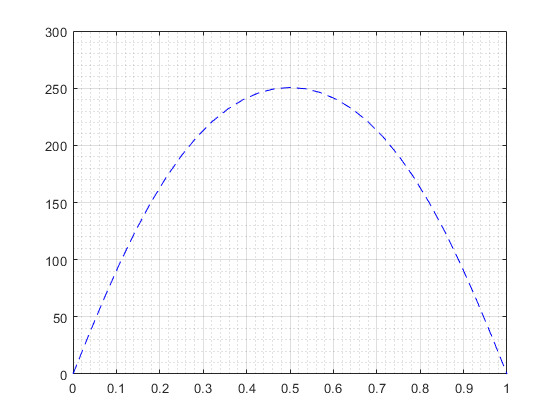

post_processing( dof, geo, mesh, U )